rho = 40;
rho = rho /100;
s = 10;
n=500;
Delta =5;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 4; 
p=100;
Omega = eye(p) + diag(rho*ones(p-1,1), 1) + diag(rho*ones(p-1,1), -1);
Sigma = inv(Omega);
M = Delta/2/ sqrt( sum( Sigma(1:s,1:s),"all") )
sparse_mean = [repelem(1,s), repelem(0,p-s)]'; %column vector
mu_0_tilde =  M * sparse_mean;
mu_0 = Sigma*mu_0_tilde;
mu_1 = -mu_0;
mu_2 = mu_0;

beta = Omega * (mu_1-mu_2);
fprintf( "delta confirmed: %f", sqrt( (mu_1-mu_2)' * beta ))
norm((mu_1-mu_2))





mu_1_mat = repmat(mu_1,  1, n/2); %each column is one observation
mu_2_mat = repmat(mu_2, 1, n/2);%each column is one observation
x_noiseless = [ mu_1_mat  mu_2_mat ];%each column is one observation 
x_noisy = x_noiseless +  mvnrnd(zeros(p,1), Sigma, n)';
X_tilde_true = x_noisy' * Omega;


cluter_code = [1,-1];
n_regression = floor(p/2);

Omega_diag_hat_even = repelem(0,p/2);
Omega_diag_hat_odd = repelem(0,p/2);
mean_now_even = zeros(p/2,n);
mean_now_odd = zeros(p/2,n);
noise_now_even =zeros(p/2,n);
noise_now_odd = zeros(p/2,n);

mean_now = zeros(p,n);
noise_now = zeros(p,n);




cluster_est_now = cluster_true;









tic
for i = 1 : n_regression
    alpha_Al = zeros([2,2]);
    E_Al = zeros([2,n]);

    for cluster = 1:2
        cluster_now = sign(cluster/2-0.7);
        g_now = (cluster_est_now == cluster_now);
        x_noisy_g_now = x_noisy(:,g_now);
        predictor_boolean = ((1:p) == (2*(i-1)+1)) | ((1:p) == (2*(i-1)+2));
        predictor_now = x_noisy_g_now(~predictor_boolean, :)';
        for j = 1:2
            boolean_now = (1:p) == (2*(i-1)+j);
            response_now = x_noisy_g_now(boolean_now,:)';
            
            model_lasso = glm_gaussian(response_now, predictor_now); 
            fit = penalized(model_lasso, @p_lasso, "standardize", true);
            AIC = goodness_of_fit('aic', fit);
            [min_aic, min_aic_idx] = min(AIC);
            beta = fit.beta(:,min_aic_idx);
            slope = beta(2:end);
            intercept = beta(1);
            E_Al(j,g_now) = response_now - intercept- predictor_now * slope;
            alpha_Al(j, cluster) = intercept;
        end
    
        
        
        
    end
    %estimation
    Omega_hat_Al = inv(E_Al*E_Al')*n;% 2 x 2
    disp(Omega_hat_Al)
    diag_Omega_hat_Al = diag(Omega_hat_Al);
    noise_Al = Omega_hat_Al*E_Al; % 2 * n
    mean_Al = zeros([2,n]);
    for cluster = 1:2
        clutser_code_now = cluter_code(cluster);
        g_now = cluster_est_now == clutser_code_now;
        n_now = sum(g_now);
        mean_Al(:,g_now) = repmat(Omega_hat_Al*alpha_Al(:,cluster), [1,n_now]);
    end
    %Omega_diag_hat( output_index ) = diag(Omega_hat_Al);
    k = i+1;
    Omega_diag_hat_odd( i ) = diag_Omega_hat_Al(1);
    Omega_diag_hat_even( i) = diag_Omega_hat_Al(2);
    mean_now_odd( i,:) = mean_Al(1,:);
    mean_now_even( i,:) = mean_Al(2,:);
    noise_now_odd( i,:) = noise_Al(1,:);
    noise_now_even( i,:) = noise_Al(2,:);
end

    1.1511    0.4084
    0.4084    1.0402

    1.0449    0.4095
    0.4095    1.1622

    1.2679    0.4239
    0.4239    1.2400

    1.2079    0.4274
    0.4274    1.1193

    1.0361    0.4508
    0.4508    1.0722

    1.0129    0.4444
    0.4444    1.1396

    1.0643    0.3943
    0.3943    1.1722

    1.0891    0.3806
    0.3806    1.0354

    1.1207    0.4291
    0.4291    1.0482

    1.1487    0.3522
    0.3522    1.1070

    1.1075    0.4475
    0.4475    1.2785

    0.9624    0.4280
    0.4280    1.0699

    1.2285    0.4989
    0.4989    1.1682

    1.1474    0.5329
    0.5329    1.3314

    1.1792    0.4886
    0.4886    1.2300

    1.3287    0.5181
    0.5181    1.1940

    1.2817    0.5928
    0.5928    1.2590

    1.2359    0.5369
    0.5369    1.2867

    1.1673    0.4489
    0.4489    1.1326

    1.0795    0.3761
    0.3761    1.1385

    1.2144    0.6038
    0.6038    1.2246

    1.0770    0.3547
    0.3547    1.1241

    1.0649    0.3603
    0.3603    1.0319

    1.1229 

toc

Elapsed time is 16.653592 seconds.


even_idx =mod((1:p),2)==0;
odd_idx = mod((1:p),2)==1;
Omega_diag_hat = repelem(0,p);
Omega_diag_hat(odd_idx) = Omega_diag_hat_odd;
Omega_diag_hat(even_idx) = Omega_diag_hat_even;


diff_omega_diag(iter) = norm(Omega_diag_hat - diag(Omega))

Unrecognized function or variable 'iter'.

mean_now(odd_idx,:) = mean_now_odd;
mean_now(even_idx,:) = mean_now_even;
noise_now(odd_idx,:) = noise_now_odd;
noise_now(even_idx,:) = noise_now_even;
x_tilde_now = mean_now + noise_now;

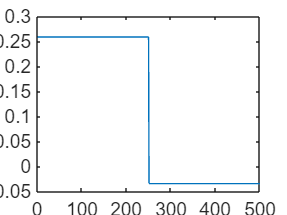


plot(mean_now(12,:))

(x_tilde_now' - X_tilde_true)./X_tilde_true

ISEE_bicluster(x_noisy, cluster_true)